rng(1000)
nbPoints = 20

nbPoints = 20

X = round(rand(1,nbPoints),3)

X =     0.6540    0.1150    0.9500    0.4820    0.8720    0.2120    0.0410    0.3970    0.2330    0.8420    0.2070    0.7420    0.3920    0.1820    0.7440    0.0700    0.8850    0.9530    0.9310    0.4150


Y = round(rand(1,nbPoints),3)

Y =     0.0290    0.9820    0.3400    0.7070    0.3620    0.0350    0.8550    0.6570    0.7660    0.5540    0.8850    0.9040    0.0100    0.0750    0.2450    0.1330    0.6980    0.3980    0.8830    0.1810


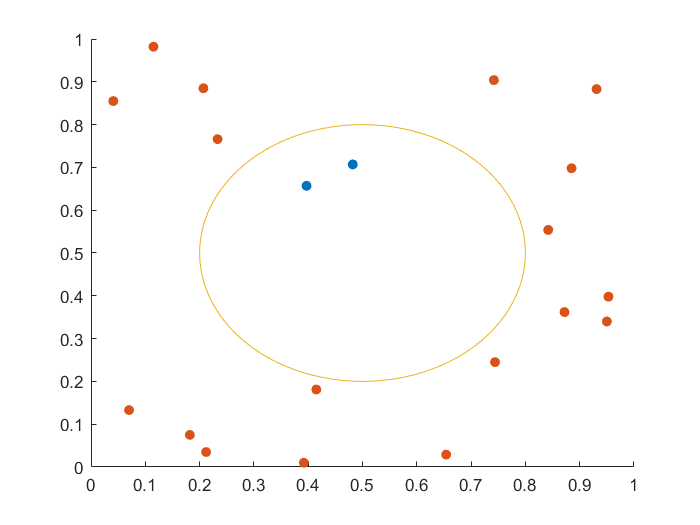


XA = {};
XB = {};
YA = {};
YB = {};

for index = 1:nbPoints
    distance = sqrt((X(index) - 0.5)^2 + (Y(index) - 0.5)^2);
    if distance <= 0.3
        XA = [XA, X(index)];
        YA = [YA, Y(index)];
    else
        XB = [XB, X(index)];
        YB = [YB, Y(index)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.3 * cos(th) + 0.5;
yunit = 0.3 * sin(th) + 0.5;



figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')
plot(xunit, yunit);